clc,clear,close all;
image1 = imread('Fig0.tif');
image2 = image1(:);
image2length = length(image2);
imageSize = size(image1);
% Compress
X = image1(:);
x = 1:1:length(X);
subplot(2,3,1),plot(x,X(x)),title('Origin pixel distrubution');

j=1;
image4(1)=1;
for z=1:1:(length(X)-1)
    if X(z)==X(z+1)
        image4(j) = image4(j) + 1;
    else data(j)=X(z);  %  data(j)代表相应的像素数据
        j=j+1;
        image4(j)=1;
    end
end
data(j)=X(length(X));
image4length=length(image4);

y=1:1:image4length ;          % 显示编码后数据信息
subplot(2,3,2),plot(y,image4(y)),title('Compressed pixel distrubution');
CR1 = image2length/image4length

CR1 = 1.1679

image4 = uint8(image4);
CR2 = imratio(image2,image4)

CR2 = 1.1679

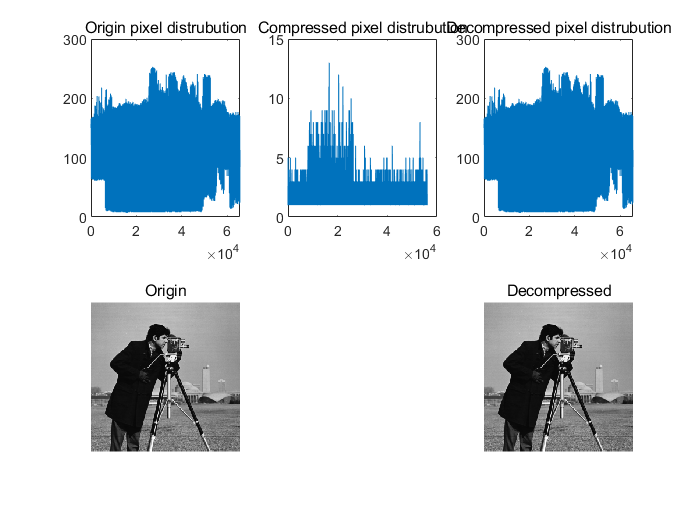

% Decompress
l = 1;
for m=1:image4length
    for n=1:1:image4(m)
        rec_image(l) = data(m);
        l = l+1;
    end
end
u = 1:1:length(rec_image);
subplot(2,3,3),plot(u,rec_image(u)),title('Decompressed pixel distrubution');

rec2_image=reshape(rec_image,imageSize(1),imageSize(2));
subplot(2,3,4),imshow(image1),title('Origin');
subplot(2,3,6),imshow(rec2_image),title('Decompressed');

RMSE = compare(rec_image,rec2_image)

RMSE = 0

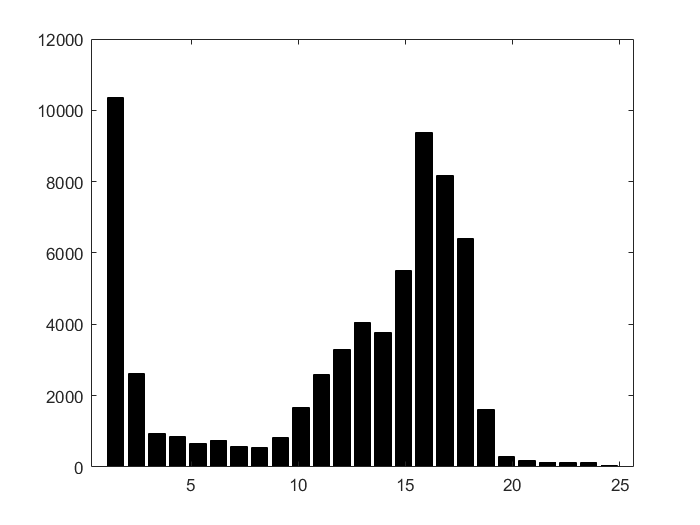

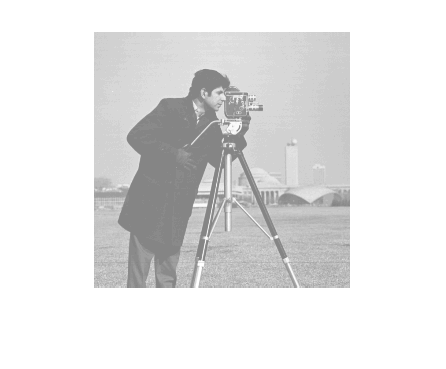

RMSE = 13.3638

clc,clear,close all;
image1 = imread('Fig0.tif');
image2 = image1*0.9;
RMSE = compare(image1,image2)

clc,clear,close all
I = imread('Fig0.tif');
st = zeros(1,length(I));
I = reshape(I,1,length(I(:)));
for i = 1:length(I)
    index = I(i);
    st(index) = st(index) + 1;
end
H = 0;
for i = 1:length(st)
    if st(i) == 0
        continue
    end
    H = H + (-(st(i)/sum(st))*log(st(i)/sum(st)));
end
H

H = 4.8588

clc,clear,close all
I = imread('Fig0.tif');
H = mat2huff(I)

H = 包含以下字段的 struct :
    size: [256 256]
     min: 32775
    hist: [1×247 uint16]
    code: [1×28856 uint16]


CR = imratio(I,H.code)

CR = 1.1356


CR2 = 0

CR2 = 0

CR2

CR2 = 0